# Summary Results Demo

Use SummaryResults function to compare the costs values for the diferent states of the plant

#### Select and check the model file

filename="D:\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(filename);

#### Select the parameters

param=struct();
if data.isResourceCost
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
end

#### Obtain the Summary Results

res=SummaryResults(data,param);
printResults(res);

Summary Flows Exergy (kW)

 Key           REF    ETAT75    ETAC75    TCND35    TBLR85      W200
—————————————————————————————————————————————————————————————————————
 B1          620.8     637.8     620.8     694.0     641.4    1172.0
 B2          317.8     326.9     317.8     390.3     339.5     599.8
 B3          281.6     289.3     281.6     317.4     301.5     531.5
 B4          294.3     302.3     294.3     331.1     313.3     555.4
 B5          220.7     220.7     215.2     197.9     220.7     220.7
 B6          194.0     194.0     189.2     167.1     194.0     194.0
 B7           59.6      59.6      58.1      53.0      59.6      59.6
 B8          244.5     244.5     238.5     238.6     244.5     244.5
 WT          245.1     245.5     245.1     246.3     244.2     462.6
 WC          230.0     230.0     230.0     230.0     230.0     230.0
 WP           14.8      15.2      14.8      15.9      13.9      27.9
 QBLR        462.1     474.8     462.1     505.9     477.2     872.1
 QEVP 

#### Show the default summary results graph

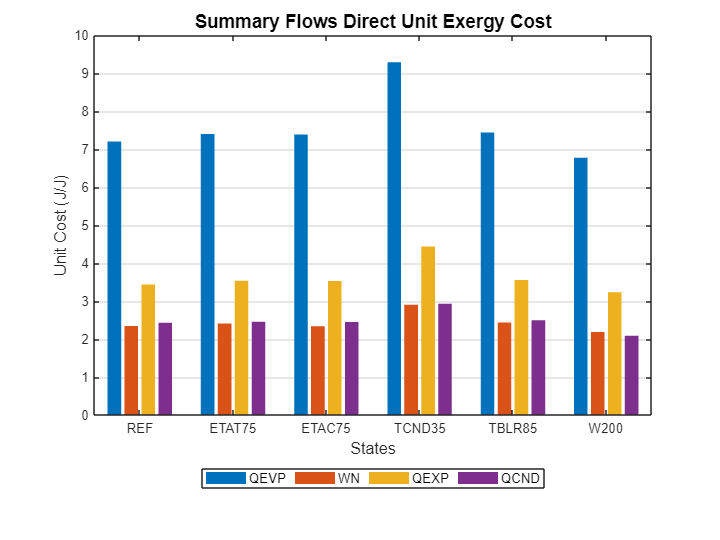

ShowGraph(res);

#### Save the summary results into an excel file

outfile='SummaryResults.xlsx';
SaveOption=true;
if SaveOption
    SaveResults(model,outfile);
end

INFO: cStatusLogger. File SummaryResults.xlsx has been saved


**Select Additional Tables for ShowResults/ShowGraph**

Show the index table for summary results

ShowResults(res,'Table',cType.TABLE_INDEX)

 Key      Description                                 Graph  
———————————————————————————————————————————————————————————————
 exergy   Summary Flows Exergy                        false  
 pku      Summary Process Unit Consumption            true   
 pI       Summary Process Irreversibility             false  
 dpc      Summary Processes Direct Exergy Cost        false  
 dpuc     Summary Processes Direct Unit Exergy Cost   true   
 dfc      Summary Flows Direct Exergy Cost            false  
 dfuc     Summary Flows Direct Unit Exergy Cost       true   
 gpc      Summary Processes Generalized Cost          false  
 gpuc     Summary Processes Generalized Unit Cost     true   
 gfc      Summary Flows Generalized Cost              false  
 gfuc     Summary Flows Generalized Unit Cost         true   



Select a table from the available tables.

tables=convertCharsToStrings(res.getListOfTables);
table=convertStringsToChars(tables(5));
tp=ShowResults(res,'Table',table);

Summary Processes Direct Unit Exergy Cost (J/J)

 Key           REF    ETAT75    ETAC75    TCND35    TBLR85      W200
—————————————————————————————————————————————————————————————————————
 BLR        1.7210    1.7185    1.7173    2.0302    1.7875    1.6479
 TRB        2.2831    2.3491    2.2772    2.8038    2.3622    2.1422
 PMP        2.8536    2.9414    2.8449    3.6422    2.9918    2.6524
 CMP        3.4375    3.5319    3.5243    4.4331    3.5498    3.2330
 EVAP       7.1978    7.3956    7.3818    9.2809    7.4330    6.7698
 GEN        2.3422    2.4079    2.3360    2.9036    2.4359    2.1874
 VEXP       3.4375    3.5319    3.5243    4.4331    3.5498    3.2330
 CND        2.4303    2.4518    2.4506    2.9287    2.4955    2.0865



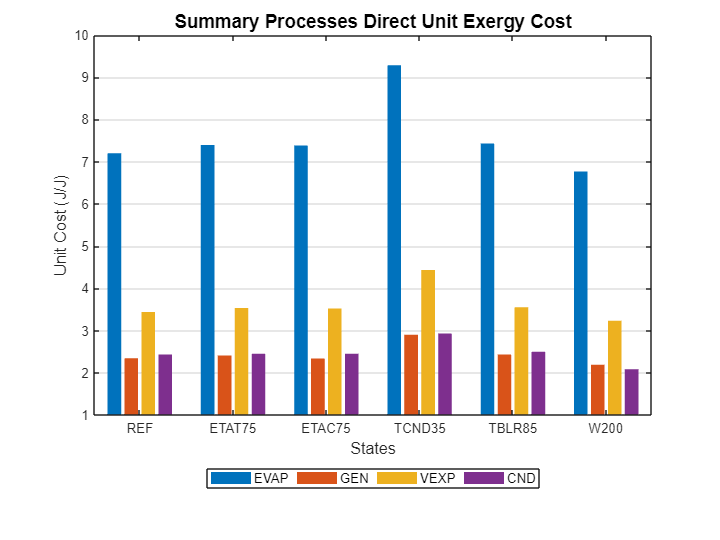

if isGraph(tp)
    ShowGraph(res,'Graph',table);
end